# Coupled Circuits - Part IV

## Inductively Coupled L circuits

Elisheva Nafha

warning('off','all')

Extract and fit sine to data

data_path_pattern = "./l_coupled_l_data/*.csv";
paths = dir(data_path_pattern);

% Generate arrays for future sine fits, where f(t) = a * sin(b*t + c)
a_sent = zeros(length(paths), 1);
b_sent = zeros(length(paths), 1);
c_sent = zeros(length(paths), 1);

a_sent_err = zeros(length(paths), 1);
b_sent_err = zeros(length(paths), 1);
c_sent_err = zeros(length(paths), 1);

a_read_V = zeros(length(paths), 1);
b_read_V = zeros(length(paths), 1);
c_read_V = zeros(length(paths), 1);

a_read_V_err = zeros(length(paths), 1);
b_read_V_err = zeros(length(paths), 1);
c_read_V_err = zeros(length(paths), 1);

% to measure the oscilloscope's accuracy
d_osc = zeros(length(paths), 1);

degrees = zeros(length(paths), 1);

% extract data, fit sine and calculate error
for i = linspace(1, length(paths), length(paths))
     degrees(i) = str2double(paths(i).name(1:2));
     data_path = sprintf("%s\\%s", paths(i).folder, paths(i).name);
     csv_recs = readtable(data_path);
     time = csv_recs.Var4;
     sent_signal = csv_recs.Var5;
     read_V = csv_recs.Var11;
     %plot(time, read_V);

     % fit sine to the sent data
     fitted_sine_sent = fit(time, sent_signal, 'sin1');
     a_sent(i) = fitted_sine_sent.a1;
     b_sent(i) = fitted_sine_sent.b1;
     c_sent(i) = fitted_sine_sent.c1;
     confint_sent = confint(fitted_sine_sent);
     a_sent_err(i) = (confint_sent(2, 1) - confint_sent(1, 1)) / 2;
     b_sent_err(i) = (confint_sent(2, 2) - confint_sent(1, 2)) / 2;
     c_sent_err(i) = (confint_sent(2, 3) - confint_sent(1, 3)) / 2;
     
     % fit sine to the read I1 data
     fitted_sine_read_V = fit(time, read_V, 'sin1');
     a_read_V(i) = fitted_sine_read_V.a1;
     b_read_V(i) = fitted_sine_read_V.b1;
     c_read_V(i) = fitted_sine_read_V.c1;
     confint_read_V = confint(fitted_sine_read_V);
     a_read_V_err(i) = (confint_read_V(2, 1) - confint_read_V(1, 1)) / 2;
     b_read_V_err(i) = (confint_read_V(2, 2) - confint_read_V(1, 2)) / 2;
     c_read_V_err(i) = (confint_read_V(2, 3) - confint_read_V(1, 3)) / 2;

end

Let us now extract voltage expected in L2:


$$\begin{array}{l}
V\left(t\right)=V_0 e^{i\left(\omega t+\phi \right)} ;\;\;V=I|Z|=\omega \textrm{LI}\;=V_0 e^{i\left(\omega t+\phi \right)} \;\Rightarrow \;I\left(t\right)=\frac{V_0 }{\omega L}e^{i\left(\omega t+\phi \right)} \;\;\\
\Rightarrow \epsilon =-L\frac{\textrm{dI}}{\textrm{dt}}=-iV_0 e^{i\left(\omega t+\phi \right)} =V_0 \sin \left(\omega t+\phi \right)\;
\end{array}$$


We expect the inducted voltage's amplitude to go like $|\epsilon |\cdot \cos \left(\alpha \right)$:

tbl = table(degrees(:), a_read_V(:));
modelfun = @(b,x) b(1) * cos(x * 2 * pi / 360);
beta0 = mean(a_sent) / 10;
% Now the next line is where the actual model computation is done.
mdl = fitnlm(tbl, modelfun, beta0);
b = mdl.Coefficients{:, 'Estimate'}

b = 0.3194

SE = mdl.Coefficients{:, 'SE'}

SE = 0.0060

Calculate measures errorbar:

d_osc = 0.1589;
d_v1 = sqrt(a_read_V_err.^2 + d_osc.^2);

Lets plot

figure()
hold on
measured_V1 = errorbar(degrees, a_read_V, d_v1, 'LineStyle','none','Marker','.', 'MarkerSize', 15, 'Color', 'Red');
degrees_spect = linspace(min(degrees), max(degrees), 1000);
fitted_V1 = plot(degrees_spect, b(1) * cos(degrees_spect * 2 * pi / 360), 'Color', 'Blue')

fitted_V1 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-5 -4.8989 -4.7978 -4.6967 -4.5956 -4.4945 -4.3934 -4.2923 -4.1912 -4.0901 -3.9890 -3.8879 -3.7868 -3.6857 -3.5846 -3.4835 -3.3824 -3.2813 -3.1802 -3.0791 -2.9780 -2.8769 -2.7758 -2.6747 -2.5736 -2.4725 -2.3714 … ] (1×1000 double)
              YData: [0.3182 0.3182 0.3182 0.3183 0.3183 0.3184 0.3184 0.3185 0.3185 0.3186 0.3186 0.3186 0.3187 0.3187 0.3187 0.3188 0.3188 0.3188 0.3189 0.3189 0.3189 0.3190 0.3190 0.3190 0.3190 0.3191 0.3191 0.3191 0.3191 0.3192 … ] (1×1000 double)

  Show 

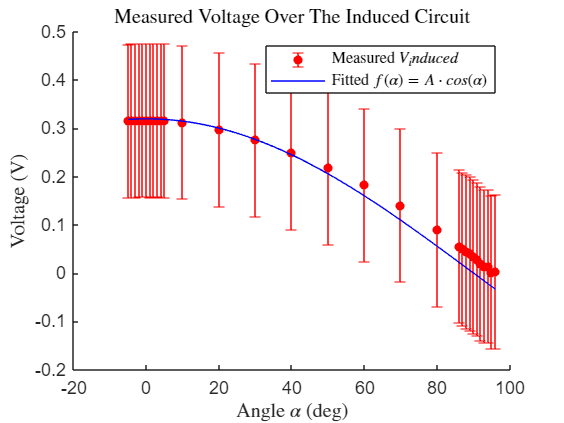

title("Measured Voltage Over The Induced Circuit", Interpreter="latex")
xlabel("Angle $\alpha$ (deg)", Interpreter="latex")
ylabel("Voltage (V)", Interpreter="latex")
h = [measured_V1, fitted_V1];
legend(h, 'Measured $V_induced$', 'Fitted $f(\alpha)=A\cdot cos(\alpha)$', 'interpreter','latex')
hold off

function std = std_given_mean(data, mean)
    N = length(data);
    std = sqrt(sum((data - mean).^2) / (N - 1));
end

function data_crit_pts = find_discrete_sine_critical_points(time, voltage, a,  w, phi)
    % find critical points analytically    
    syms t real;
    f = a * sin(w * t + phi);
    df = matlabFunction(diff(f, t));
    f = matlabFunction(f);
    crit_pts_indices = find(gradient(sign(df(time)))~=0);
    crit_pts = round(mean(reshape(time(crit_pts_indices),2,[])), 5);

    % find the critical points in the data
    data_crit_pts = voltage(crit_pts_indices);
end

function fit_DC_coupled(time, voltage, initial_guess)
    start_idx = find(time > 0, 1, "first")
    tbl = table(time(start_idx:end), voltage(start_idx:end));
    modelfun = @(b,x) b(1) * exp(-b(2)*x) .* cos((b(3) + b(4)) / 2 * x) .* cos((b(3) - b(4)) / 2 * x);
    beta0 = initial_guess;
    % Now the next line is where the actual model computation is done.
    mdl = fitnlm(tbl, modelfun, beta0);
    b = mdl.Coefficients{:, 'Estimate'}
    SE = mdl.Coefficients{:, 'SE'}
    figure()
    hold on
    plot(time, voltage)
    title("Coupled RLC with DC and C_c=1.2nF", Interpreter="latex")
    xlabel("Voltage (V)", Interpreter="latex")
    ylabel("time (s)", Interpreter="latex")
    %plot(time, b(1) * exp(-b(2)*time) .* cos((b(3) + b(4)) / 2 * time) .* cos((b(3) - b(4)) / 2 * time))
    hold off
end

function plot_fit(time, signal, a, b, c)
    figure();
    hold on
    sine_fit = a * sin(b * time + c);
    scatter(time, signal);
    plot(time, sine_fit);
    title(sprintf("Sine Fit %d * sin(%d * t + %d)", a, b, c));
    hold off
end